## Tarea 3

## Alejandro Brenes Calderón - C21319

## Eyeri Méndez Méndez - C24765

### **Desarrollo**

#### **1.**

a)

function [Q, R] = qr1(A)

    % Obtenemos las dimensiones de la matriz A
    [m, n] = size(A);

    % Inicializamos las matrices Q y R
    Q = zeros(m, n);
    R = zeros(n, n);
    
    % Iteramos sobre cada columna de A para construir Q y R
    for j = 1:n
        % Seleccionamos la j-ésima columna de A
        vj = A(:, j); 
        
        % Eliminamos la proyección de Q(:, i) sobre vj
        for i = 1:j-1
            % El coeficiente R(i, j) corresponde al producto 
            % interno entre Q(:, i) y A(:, j)
            R(i, j) = Q(:, i)' * A(:, j);

            % Actualizamos vj restando la proyección de Q(:, i)
            vj = vj - R(i, j) * Q(:, i);
        end
        
        % Calculamos el valor de R(j, j) como la norma de vj
        R(j, j) = norm(vj);
        
        % La j-ésima columna de Q corresponde vj normalizado
        Q(:, j) = vj / R(j, j);
    end
end

b)

function [Q, R] = qr2(A)

    % Obtenemos las dimensiones de la matriz A
    [m, n] = size(A);

    % Inicializamos las matrices Q y R
    Q = zeros(m, n);
    R = zeros(n, n);

    % Copiamos la matriz A en una matriz V que se irá modificando
    V = A;

    % Iteramos sobre cada columna de A para construir Q y R
    for i = 1:n
        % Calculamos el valor de R(i, i) como la norma del 
        % vector actual V(:, i)
        R(i, i) = norm(V(:, i));

        % Normalizamos V(:, i) para obtener el vector 
        % ortonormal Q(:, i)
        Q(:, i) = V(:, i) / R(i, i);

        % Iteramos sobre cada columna posterior a la actual
        for j = i+1:n

            % % Calculamos el coeficiente de proyección R(i, j) 
            % como el producto interno entre Q(:, i) y V(:, j)
            R(i, j) = Q(:, i)' * V(:, j);

            % Restamos la proyección de V(:, j) en la 
            % dirección de Q(:, i)
            V(:, j) = V(:, j) - R(i, j) * Q(:, i);
        end
    end
end

c)

function [Q, R] = qr3(A)

    % Obtenemos las dimensiones de la matriz A
    [m, n] = size(A);

    % Copiamos la matriz A en la matriz R que será triangular 
    % superior
    R = A;

    % Inicializamos matriz la matriz M como la identidad de 
    % tamaño m
    M = eye(m);

    % Iteramos sobre las columnas de A
    for j = 1:n
        % Extraemos el vector que va desde la fila j hasta m en 
        % la columna j de R
        x = R(j:m, j);

        % Creamos el vector canónico e1
        e1 = zeros(length(x), 1);
        e1(1) = 1;
        
        % Calculamos el vector de Householder vj y lo normalizamos
        vj = sign(x(1)) * norm(x) * e1 + x;
        vj = vj / norm(vj); 

        % Actualizamos las submatrices de R y M aplicando la 
        % transformación de Householder
        R(j:m, j:n) = R(j:m, j:n) - 2 * vj * (vj' * R(j:m, j:n));
        M(j:m, :) = M(j:m, :) - 2 * vj * (vj' * M(j:m, :));
    end

    % Asignamos la matriz Q como la transpuesta de M
    Q = M';
end

d)

% Tamaño de la matriz A
m = 20;

% Generamos una matriz aleatoria A
A = rand(m);

% Matriz identidad de tamaño m x m
I = eye(m);

% Realizamos la factorización QR de la matriz A usando los 3 
% algoritmos de los incisos anteriores
[Q1, R1] = qr1(A);
[Q2, R2] = qr2(A);
[Q3, R3] = qr3(A);

% Calculamos la norma 2 de la diferencia entre A y la 
% factorización QR de A para cada algoritmo
norma_QR1 = norm(A - Q1 * R1);
norma_QR2 = norm(A - Q2 * R2);
norma_QR3 = norm(A - Q3 * R3);

% Calculamos la norma 2 de la diferencia entre Q*Q^T y 
% la matriz identidad I para cada cada algoritmo
norma_QQT1 = norm(Q1 * Q1' - I);
norma_QQT2 = norm(Q2 * Q2' - I);
norma_QQT3 = norm(Q3 * Q3' - I);

fprintf('Usando qr1 se tiene:\n');

Usando qr1 se tiene:


fprintf('||A - QR||_2 = %.20f\n', norma_QR1);

||A - QR||_2 = 0.00000000000000082128


fprintf('||QQ^T - I||_2 = %.20f\n\n', norma_QQT1);

||QQ^T - I||_2 = 0.00000000000029766407




fprintf('Usando qr2 se tiene:\n');

Usando qr2 se tiene:


fprintf('||A - QR||_2 = %.20f\n', norma_QR2);

||A - QR||_2 = 0.00000000000000077306


fprintf('||QQ^T - I||_2 = %.20f\n\n', norma_QQT2);

||QQ^T - I||_2 = 0.00000000000003003783




fprintf('Usando qr3 se tiene:\n');

Usando qr3 se tiene:


fprintf('||A - QR||_2 = %.20f\n', norma_QR3);

||A - QR||_2 = 0.00000000000000377676


fprintf('||QQ^T - I||_2 = %.20f\n\n', norma_QQT3);

||QQ^T - I||_2 = 0.00000000000000138453



Podemos ver que numericamente sí se cumple que $A = QR$, ya que la norma $2$ de la diferencia entre estas dos matrices es cercana a $0$ usando cualquiera de los $3$ algoritmos.

De igual manera, numericamente hablando podemos afirmar que $Q$ es ortogonal, ya que la norma $2$ entre $Q \cdot Q^T$ y la matriz identidad $I$ es cercana a $0$.

Además, podríamos decir que los algoritmos $qr1$ y $qr2$ son mejores que el $qr3$, ya que la norma $2$ $||A - QR||_2$ es más cercana a $0$ en los dos primeros algoritmos (por un decimal); sin embargo, el algoritmo $qr3$ presenta un mejor resultado en cuanto a la ortogonalización de $Q$, pues la norma $2$ $||QQ^T - I||_2$ es más cercana a $0$ (por un decimal).

A pesar de lo anterior, los $3$ algoritmos dan muy buenos resultados.

e)

% Generamos la matriz de Hilbert
A = hilb(m);

% Realizamos la factorización QR de la matriz A usando el 
% comando de Matlab y los 3 algoritmos de los incisos anteriores
[Q1_H, R1_H] = qr1(A);
[Q2_H, R2_H] = qr2(A);
[Q3_H, R3_H] = qr3(A);
[Q, R] = qr(A);

% Calculamos la norma 2 de la diferencia entre A y la 
% factorización QR de A para cada algoritmo
norma_QR1_H = norm(A - Q1_H * R1_H);
norma_QR2_H = norm(A - Q2_H * R2_H);
norma_QR3_H = norm(A - Q3_H * R3_H);
norma_QR = norm(A - Q * R);

% Calculamos la norma 2 de la diferencia entre Q*Q^T y 
% la matriz identidad I para cada cada algoritmo
norma_QQT1_H = norm(Q1_H * Q1_H' - I);
norma_QQT2_H = norm(Q2_H * Q2_H' - I);
norma_QQT3_H = norm(Q3_H * Q3_H' - I);
norma_QQT = norm(Q * Q' - I);

fprintf('Usando qr1 se tiene:\n');

Usando qr1 se tiene:


fprintf('||A - QR||_2 = %.20f\n', norma_QR1_H);

||A - QR||_2 = 0.00000000000000008464


fprintf('||QQ^T - I||_2 = %.20f\n\n', norma_QQT1_H);

||QQ^T - I||_2 = 12.97161351231601145173




fprintf('Usando qr2 se tiene:\n');

Usando qr2 se tiene:


fprintf('||A - QR||_2 = %.20f\n', norma_QR2_H);

||A - QR||_2 = 0.00000000000000008098


fprintf('||QQ^T - I||_2 = %.20f\n\n', norma_QQT2_H);

||QQ^T - I||_2 = 0.99895633841753628257




fprintf('Usando qr3 se tiene:\n');

Usando qr3 se tiene:


fprintf('||A - QR||_2 = %.20f\n', norma_QR3_H);

||A - QR||_2 = 0.00000000000000041743


fprintf('||QQ^T - I||_2 = %.20f\n\n', norma_QQT3_H);

||QQ^T - I||_2 = 0.00000000000000113713




fprintf('Usando qr de Matlab se tiene:\n');

Usando qr de Matlab se tiene:


fprintf('||A - QR||_2 = %.20f\n', norma_QR);

||A - QR||_2 = 0.00000000000000042275


fprintf('||QQ^T - I||_2 = %.20f\n\n', norma_QQT);

||QQ^T - I||_2 = 0.00000000000000135288



En este caso podemos ver que, a pesar de que los $3$ algoritmos desarrollados dan buenos resultados en cuanto a la norma $2$ $||A - QR||_2$, el algoritmo que más se acerca al resultado de la función $qr$ de Matlab es el $qr3$, pues los dos primeros algoritmos dan valores bastante altos de la norma $2$ $||QQ^T - I||_2$, por lo que se concluye que el algoritmo $qr3$ es el mejor si se usa una matriz de Hilbert de tamaño $20\times20$.

#### **2.**

#### **3.**

a) 

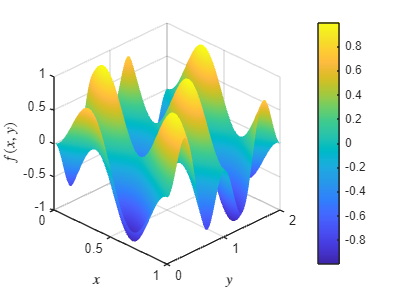

% Definimos los vectores requeridos
x = linspace(0, 1, 100);
y = linspace(0, 2, 200);

% Generamos la malla de puntos equidistantes
[xx, yy] = meshgrid(x, y);

% Definimos la función requerida
f = @(x, y) sin(2*pi*(x+y)) .* sin(pi*(x-y));

% Graficamos
figure;
surf(xx, yy, f(xx, yy));

% Mejoras en la visualización
shading interp; % Suaviza el sombreado
colorbar; % Añade una barra de color que indica los valores
view(45, 30); % Cambia el ángulo de vista
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$f(x, y)$', 'Interpreter', 'latex');
grid on;

b) 

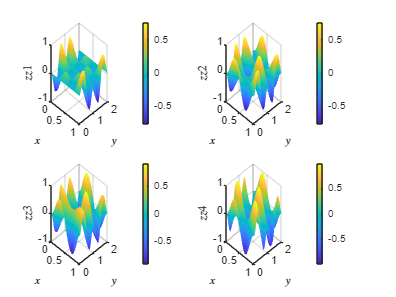

% Definimos la matriz zz
zz = f(xx, yy);

% Calculamos su descomposición en valores singulares
[U, S, V] = svd(zz);

% Guardamos los valores singulares
val_sing = diag(S);

% Calculamos las aproximaciones de rango 1, 2, 3 y 4
zz1 = val_sing(1) * U(:, 1) * V(:, 1)';
zz2 = zz1 + val_sing(2) * U(:, 2) * V(:, 2)';
zz3 = zz2 + val_sing(3) * U(:, 3) * V(:, 3)';
zz4 = zz3 + val_sing(4) * U(:, 4) * V(:, 4)';

% Graficamos las anteriores aproximaciones
figure;

subplot(2, 2, 1);
surf(xx, yy, zz1);
shading interp;
colorbar;
view(45, 30);
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$zz1$', 'Interpreter', 'latex');
grid on;

subplot(2, 2, 2);
surf(xx, yy, zz2);
shading interp;
colorbar;
view(45, 30);
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$zz2$', 'Interpreter', 'latex');
grid on;

subplot(2, 2, 3);
surf(xx, yy, zz3);
shading interp;
colorbar;
view(45, 30);
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$zz3$', 'Interpreter', 'latex');
grid on;

subplot(2, 2, 4);
surf(xx, yy, zz4);
shading interp;
colorbar;
view(45, 30);
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$zz4$', 'Interpreter', 'latex');
grid on;

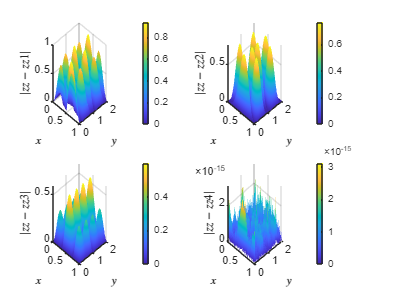


% Graficamos el error absoluto para cada aproximación
figure;

subplot(2, 2, 1);
surf(xx, yy, abs(zz - zz1));
shading interp;
colorbar;
view(45, 30);
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$|zz - zz1|$', 'Interpreter', 'latex');
grid on;

subplot(2, 2, 2);
surf(xx, yy, abs(zz - zz2));
shading interp;
colorbar;
view(45, 30);
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$|zz - zz2|$', 'Interpreter', 'latex');
grid on;

subplot(2, 2, 3);
surf(xx, yy, abs(zz - zz3));
shading interp;
colorbar;
view(45, 30);
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$|zz - zz3|$', 'Interpreter', 'latex');
grid on;

subplot(2, 2, 4);
surf(xx, yy, abs(zz - zz4));
shading interp;
colorbar;
view(45, 30);
xlabel('$x$', 'Interpreter', 'latex');
ylabel('$y$', 'Interpreter', 'latex');
zlabel('$|zz - zz4|$', 'Interpreter', 'latex');
grid on;

En los gráficos de las aproximaciones de rango 1, 2, 3 y 4 podemos ver que la aproximación por rango de la matriz **zz** inicia siendo mala y mejora conforme agregamos un rango más a la aproximación, como es de esperar. Con las aproximaciones de rango 3 y 4 podemos ver que hay poca o nula diferencia respecto al gráfico original de $f(x, y)$.

Respecto a los gráficos de los errores absolutos, se observa que el error disminuye conforme agregamos un rango más a la aproximación, complementando lo mencionado anteriormente de los gráficos de las aproximaciones por rango. Lo más relevante de estos últimos $4$ gráficos es que el error absoluto asociado a la aproximación de rango $4$ es muy pequeño, pues está en escala de $10^{-15}$, lo cual indica que esta aproximación es muy cercana a la matriz original **zz**; es decir, solo necesitamos los primeros $4$ valores singulares para replicar con una buena precisión la función $f(x, y)$.

c)

El rango de **zz **está dado por:

disp(rank(zz));

     4



Dado que el rango es $4$, la matriz tendrá $4$ valores singulares positivos y $96$ iguales a $0$.

Veamos si esto es cierto numéricamente usando código:

disp(sum(val_sing == 0));

     0




r = zeros(1, sum(val_sing > 0));

for i = 1:length(r)
    if val_sing(i) > 0
        r(i) = val_sing(i);
        disp(r(i));
    end
end

   35.7919

   35.4410

   35.0901

   35.0901

   3.1790e-14

   1.8952e-14

   1.7830e-14

   1.6726e-14

   1.5477e-14

   1.4612e-14

   1.2664e-14

   1.2120e-14

   1.1878e-14

   1.0854e-14

   1.0348e-14

   9.6574e-15

   9.4689e-15

   8.7769e-15

   8.4719e-15

   7.9815e-15

   7.6582e-15

   7.6408e-15

   7.5436e-15

   7.2806e-15

   6.4777e-15

   6.0700e-15

   5.8717e-15

   5.7246e-15

   5.2695e-15

   4.6528e-15

   4.5566e-15

   4.4588e-15

   3.6792e-15

   3.6547e-15

   3.5251e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.5192e-15

   3.51

Como se puede apreciar, en términos numéricos la matriz cuenta con $4$ valores singulares positivos y el resto iguales a $0$, ya que el valor de estos últimos es casi igual a la precisión de la máquina, por lo que, al ser valores muy pequeños, se consideran $0$.

d)

Usando las siguientes identidades trigonométricas:


$$2 \cdot sin(x) \cdot sin(y) = cos(x-y) - cos(x+y)$$



$$cos(x + y) = cos(x) \cdot cos(y) - sin(x) \cdot sin(y)$$


Se tiene que:


$$g(x, y) = 2\cdot sin(2\pi (x+y)) \cdot sin(\pi(x-y)) = 2\cdot sin(2\pi \hspace{0.1mm} x+ 2\pi \hspace{0.1mm} y) \cdot sin(\pi \hspace{0.1mm} x- \pi \hspace{0.1mm} y) =$$



$$= cos(2\pi \hspace{0.1mm} x + 2\pi \hspace{0.1mm} y - (\pi \hspace{0.1mm} x - \pi \hspace{0.1mm} y)) - cos(2\pi \hspace{0.1mm} x + 2\pi \hspace{0.1mm} y + (\pi \hspace{0.1mm} x - \pi \hspace{0.1mm} y)) =$$



$$cos(\pi \hspace{0.1mm} x + 3\pi \hspace{0.1mm} y) - cos(3\pi \hspace{0.1mm} x + \pi \hspace{0.1mm} y) =$$



$$= cos(\pi \hspace{0.1mm} x) \cdot cos(3\pi \hspace{0.1mm} y) - sin(\pi \hspace{0.1mm} x) \cdot sin(3\pi \hspace{0.1mm} y) - [ cos(3\pi \hspace{0.1mm} x) \cdot cos(\pi \hspace{0.1mm} y) - sin(3\pi \hspace{0.1mm} x) \cdot sin(\pi \hspace{0.1mm} y)] =$$



$$= cos(\pi \hspace{0.1mm} x) \cdot cos(3\pi \hspace{0.1mm} y) - sin(\pi \hspace{0.1mm} x) \cdot sin(3\pi \hspace{0.1mm} y) - cos(3\pi \hspace{0.1mm} x) \cdot cos(\pi \hspace{0.1mm} y) + sin(3\pi \hspace{0.1mm} x) \cdot sin(\pi \hspace{0.1mm} y)$$



$$\Rightarrow f(x, y) = \frac{1}{2} \cdot g(x, y)$$


De esta manera, notamos que $f(x, y)$ se puede expresar como una suma de $4$ términos, donde cada uno corresponde al producto de una función de $x$ y una función de $y$, es decir, tenemos que:


$$f(x, y) = A(x) \cdot B(y) + C(x) \cdot D(y) + E(x) \cdot F(y) + G(x) \cdot H(y)$$


Esta forma sugiere que la matriz **zz**, que es la evaluación de $f(x, y)$ en la malla $(xx, yy)$, se puede descomponer en una suma de $4$ matrices, cada una de rango $1$.

Así, cada término de la suma que compone $f(x, y)$ contribuye con un rango a la matriz **zz**, por lo que esta cuenta rango $4$. Esto se debe a que cada uno de dichos términos representará una matriz de rango $1$ al evaluar $f(x, y)$ en $(xx, yy)$, pues cada término sería el producto de dos vectores, generando la matriz de rango $1$ mencionada.

Por lo tanto, al ser **zz** una matriz de rango 4, esta contará con $4$ valores singulares positivos y el resto iguales a $0$, tal y como se obtuvo en el inciso c).

#### **4.**

#### **5.**

**6.**

Sea $r$ el rango de la matriz $A$. Como $x$ está en el espacio fila de $A$, se puede expresar como una combinación lineal de las primeras $r$ columnas de $V$, por lo que se tiene que:


$$x = \sum_{i=1}^{r} z_i \cdot v_i$$


Luego, como $A = U \Sigma V^T$, tenemos que:


$$A = \sum_{k=1}^{r} u_k \cdot \sigma_k \cdot v_k^T$$


Por lo tanto, 


$$y = Ax = \sum_{k=1}^r u_k \cdot \sigma_k \cdot v_k^T \cdot \sum_{j=1}^r z_j \cdot v_j = \sum_{k=1}^r u_k \cdot \sigma_k \cdot \sum_{j=1}^r z_j \cdot (v_k^T \cdot v_j)$$


Como $v_k^T \cdot v_j$ es $0$ si $k \neq j$ y $1$ si $k = j$, ya que son vectores ortogonales, obtenemos que:


$$y = \sum_{k=1}^r u_k \cdot \sigma_k \cdot z_k$$


Por otro lado, de la definición de $A^+$ se tiene que:


$$A^+ = \sum_{i=1}^r v_i \cdot \frac{1}{\sigma_i} \cdot u_i^T$$


De esta manera, y como $u_i^T \cdot u_k$ es $0$ si $i \neq k$ y $1$ si $i = k$, pues son vectores ortogonales, tenemos que:


$$x = \sum_{i=1}^{r} z_i \cdot v_i = \sum_{i=1}^{r} z_i \cdot v_i \cdot \frac{1}{\sigma_i} \cdot \sigma_i \cdot u_i^T \cdot u_i$$



$$\Rightarrow x = \sum_{i=1}^r v_i \cdot \frac{1}{\sigma_i} \cdot \sum_{k=1}^r (u_i^T \cdot u_k) \cdot \sigma_k \cdot z_k$$



$$\Rightarrow x = \sum_{i=1}^r v_i \cdot \frac{1}{\sigma_i} \cdot u_i^T \cdot \sum_{k=1}^r u_k \cdot \sigma_k \cdot z_k$$



$$\Rightarrow x = A^+y$$


**7.**

a)

% Definimos la función f(x, c)
function fxc = fxc(x, c)
    fxc = c(1) * exp(-c(2) * x) .* sin(c(3) * x + c(4));
end

% Definimos el valor exacto de c
c_exact = [1; 1/2; 2; 0];

% Cargamos los datos
load('data.mat');

% Ordenamos los datos
[x, indices] = sort(x);
y = y(indices);

b)

% Definimos la matriz J(c)
function J = Jacobiano(x, c)
    % Inicializamos la matriz con sus respectivas dimensiones
    J = zeros(length(x), 4);

    % Determinamos cada columna de la matriz a partir de las
    % derivadas parciales de f(x, c) respecto a los c_j
    J(:, 1) = exp(-c(2) * x) .* sin(c(3) * x + c(4));
    J(:, 2) = -c(1) * x .* exp(-c(2) * x) .* sin(c(3) * x + c(4));
    J(:, 3) = c(1) * exp(-c(2) * x) .* x .* cos(c(3) * x + c(4));
    J(:, 4) = c(1) * exp(-c(2) * x) .* cos(c(3) * x + c(4));
end

% Definimos una función que implementa el algoritmo
function [ck, k, norma_deltas_ck, num_condicion] = min_cuadrados(...
    x, y, c0, tol)
    % Inicializamos el vector de parámetros ck con el valor 
    % inicial c0
    ck = c0;

    % Definimos vectores para almacenar la norma del cambio 
    % de ck en cada iteración y el número de condición de la 
    % matriz Jacobiana
    norma_deltas_ck = zeros(1, 10);
    num_condicion = zeros(1, 10);

    % Calculamos el valor de la función g y del Jacobiano J 
    % en el punto actual ck
    g_ck = fxc(x, ck);
    J_ck = Jacobiano(x, ck);
    
     % Calculamos el cambio en los parámetros (delta_ck) 
     % resolviendo el sistema J_ck * delta_ck = y - g_ck
    delta_ck = J_ck \ (y - g_ck);
    
    % Guardamos la norma infinita de delta_ck y el número 
    % de condición de J_ck
    norma_deltas_ck(1) = norm(delta_ck, Inf);
    num_condicion(1) = cond(J_ck);

    % Inicializamos el contador de iteraciones k
    k = 0;

    % Ejecutamos el bucle hasta que el cambio en ck sea menor 
    % que la tolerancia
    while norma_deltas_ck(k+1) > tol

        % Actualizamos ck sumando el cambio calculado
        ck = ck + delta_ck;

        % Recalculamos la función g y el Jacobiano J en el nuevo 
        % punto ck
        g_ck = fxc(x, ck);
        J_ck = Jacobiano(x, ck);

        % Calculamos el nuevo cambio en los parámetros
        delta_ck = J_ck \ (y - g_ck);

        % Aumentamos el contador de iteraciones
        k = k+1;

        % Guardamos la norma infinita del cambio actual y 
        % el número de condición de J_ck
        norma_deltas_ck(k+1) = norm(delta_ck, Inf);
        num_condicion(k+1) = cond(J_ck);
    end

    % Redimensionamos los vectores para que solo contengan las
    % iteraciones realizadas
    norma_deltas_ck = norma_deltas_ck(1:k+1);
    num_condicion = num_condicion(1:k+1);
end

c)

% Definimos c0
c0 = [1.1; 0.4; 2.1; 0.2];

% Ejecutamos el algoritmo de mínimos cuadrados
[ck, k, norma_deltas_ck, num_condicion] = min_cuadrados(x, y, ...
    c0, 1e-8);

% Se muestra el número de iteraciones requeridas
fprintf('Número de iteraciones requeridas: %d\n', k);

Número de iteraciones requeridas: 6


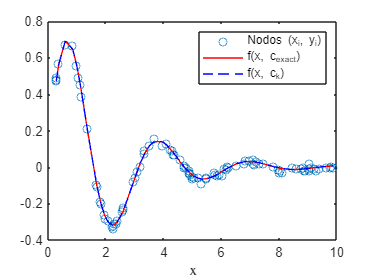


% Graficamos los puntos (x_i, y_i), la función exacta y 
% la función aproximada
figure;
plot(x, y, 'o', 'DisplayName', 'Nodos (x_i, y_i)');
hold on;
plot(x, fxc(x, c_exact), 'r', 'DisplayName', 'f(x, c_{exact})');
plot(x, fxc(x, ck), 'b--', 'DisplayName', 'f(x, c_k)');
legend;
xlabel('x', 'Interpreter', 'latex');
hold off;

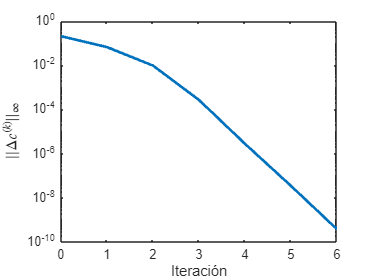


% Graficamos la norma infinita de delta_ck en función de k
figure;
semilogy(0:k, norma_deltas_ck, 'LineWidth', 2);
xlabel('Iteración');
ylabel('$||\Delta c^{(k)}||_{\infty}$', 'Interpreter', 'latex');

Observando el anterior gráfico se puede deducir que el valor inicial $c_0$ está cerca de la solución ya que se requieren pocas iteraciones para obtener la tolerancia dada, además, también se puede apreciar que la convergencia de $||\Delta c^{(k)}||_{\infty}$ pareciera ser cuadrática, lo cual es un buen indicio de que la condición inicial converge rapidamente a la solución usando una tolerancia de $10^{-8}$, lo cual indica que el algoritmo se comporta eficientemente para este valor de $c_0$.

d)

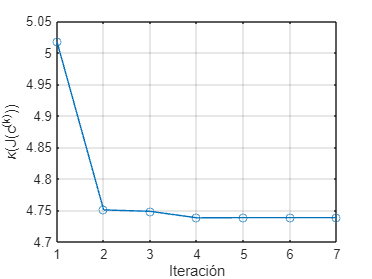

% Graficamos el número de condición
figure;
plot(1:length(num_condicion), num_condicion, '-o');
xlabel('Iteración');
ylabel('\kappa(J(c^{(k)}))');
grid on;

El anterior gráfico nos indica cómo cambia la sensibilidad de la matriz Jacobiana $J(c^{(k)})$ respecto a perturbaciones en los datos durante el algoritmo. En el gráfico podemos apreciar que el número de condición tiende a disminuir y estabilizarse en las iteraciones finales, lo cual es un buen indicador de que el algoritmo se está acercando a una solución estable y bien condicionada, complementando lo que explicado en el inciso anterior.

e)

% Definimos el nuevo valor inicial c0
c0 = [1; 1; 1; 1];

% Ejecutamos el algoritmo de mínimos cuadrados
[ck, k, norma_deltas_ck, num_condicion] = min_cuadrados(x, y, ...
    c0, 1e-8);


% Se muestra el número de iteraciones requeridas
fprintf('Número de iteraciones requeridas: %d\n', k);

Número de iteraciones requeridas: 4


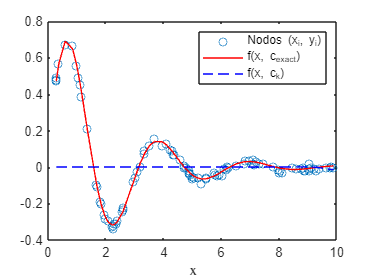


% Graficamos los puntos (x_i, y_i), la función exacta y 
% la función aproximada
figure;
plot(x, y, 'o', 'DisplayName', 'Nodos (x_i, y_i)');
hold on;
plot(x, fxc(x, c_exact), 'r', 'DisplayName', 'f(x, c_{exact})');
plot(x, fxc(x, ck), 'b--', 'DisplayName', 'f(x, c_k)');
legend;
xlabel('x', 'Interpreter', 'latex');
hold off;

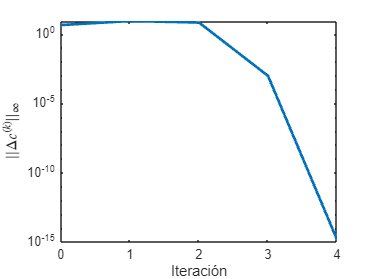


% Graficamos la norma infinita de delta_ck en función de k
figure;
semilogy(0:k, norma_deltas_ck, 'LineWidth', 2);
xlabel('Iteración');
ylabel('$||\Delta c^{(k)}||_{\infty}$', 'Interpreter', 'latex');

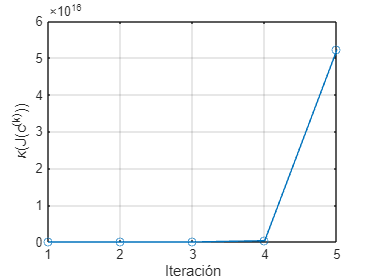


% Graficamos el número de condición
figure;
plot(1:length(num_condicion), num_condicion, '-o');
xlabel('Iteración');
ylabel('\kappa(J(c^{(k)}))');
grid on;

En este caso pareciera que la convergencia es más rápida pues solo se hacen 4 iteraciones, además de que $||\Delta c^{(k)}||_{\infty}$ converge a un número más pequeño; sin embargo, observando el gráfico del número de condición en función de $k$, podemos ver que $\kappa(J(c^{(k)}))$ aumenta considerablemente en la última iteración (la escala del gráfico está en $10^{16}$), lo que sugiere que en este último paso el algoritmo se vuelve más sensible a errores y que pequeñas variaciones en los datos producen a grandes cambios en $\Delta c^{(k)}$. 

Esto dificulta la convergencia del valor inicial $c_0$, pues el aumento es demasiado grande en esta última iteración. Además, el número de condición tan alto en dicha iteración implica que el sistema puede ser inestable numericamente, indicando que la solución pierde precisión en esa iteración.

Esto se ve reflejado en el gráfico de la función aproximada $f(x, \textbf{c}^{(k)})$, la cual se puede ver que es practicamente una recta horizontal que pasa por $0$, por lo que se aproxima de mala manera a la función exacta $f(x, \textbf{c}_{exact})$. Esto se debe a que el primer valor de $\textbf{c}^{(k)}$ es practicamente $0$ ($c_1 \approx 0$). 

Además, las advertencias que Matlab muestra indican que la matriz Jacobiana $J(\textbf{c}^{(k)})$ en ciertos pasos del algoritmo tiene un rango menor al número de columnas, lo que hace que el sistema de ecuaciones sea mal condicionado o indeterminado para esos valores de $c$.

Por lo tanto, el nuevo valor inicial $c_0$ no es apropiado para el algoritmo.

**8.**